## Dynamic Mode Decomposition

A method to reduce the dimensionality of an algorithm. It is seen as an application extracted from the idea of Koopman Spectral analysis.

We consider this method to be more data-driven and on futher explain DMD for higher order dimension non-linear systems. 

Basic idea

Non-linear to best linear approximation,


$$\frac{d\overset{\_}{x} }{\mathrm{dt}}=f\left(\overset{\_}{x} ,t,\mu \right)\to \frac{d\overset{\_}{x} }{\mathrm{dt}}=A\overset{\_}{x}$$


We measure $x$ for any time-point,


$$x_j =\overset{\_}{x} \left(t_j \right)$$


So,


$$\begin{array}{l}
X=\left\lbrack x_1 \;\;\;x_2 \;\;\;\;x_3 \;\;\cdots \cdots \;\;x_{m-1} \;\right\rbrack \\
X\;\prime =\left\lbrack x_2 \;\;\;x_3 \;\;\;\;x_4 \;\;\cdots \cdots \;\;x_m \;\right\rbrack 
\end{array}$$


Our objective is to find the best matrix that takes $X$ to $X\;\prime \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \;X\;\prime =\mathrm{AX}$

Here matrix** A** is seen as an operator that takes us $\Delta t$ times into the future from $X\;\mathrm{to}\;X\;\prime$

Now from the equation we can calculate $X$ by multiplying its respective pseudo inverse on both sides,

Final equation $\longrightarrow \;A=X\;\prime X^+$ 

This equation is the exact depiction of working of DMD but cannot be practically implemented in data-driven cases. Given our $X$ is has N columns multiplied by N rows of its pseudo inverse we get NxN matrix **A** which is computationally not feasible. So we can define it as an algorithm.

**Step 1:** Decompose $X$ using SVD 

                    
$$X=U\Sigma V^*$$


       We reduce the rank using rank truncation and use that as the subspace for building the model

                    
$$X=U_r \Sigma_r {V^* }_r$$
 

**Step 2:**   

                  
$$\begin{array}{l}
A=X\;\prime X^+ \\
\;\;\;\;=X\;\prime \;V\;\Sigma^{-1} {\;U}^* 
\end{array}$$
 

        We will be working with a similarity transform of A dentoted as $\overset{~}{A}$

                   
$$\begin{array}{l}
\overset{~}{A} =U^* A\;U\\
{\overset{~}{A} }_{\;\mathrm{rxr}} ={\;U}^* X\;\prime \;V\;\Sigma^{-1} 
\end{array}$$


**Step 3:**

        we do an eigenvalue decomposition

                    
$$\hat{\;A} W=W\Lambda$$


       where $W\;\mathrm{is}\;\left\lbrack \begin{array}{c}
\mathrm{eigenvectors}
\end{array}\right\rbrack \;\mathrm{and}\;\Lambda \;\mathrm{is}\;\left\lbrack \begin{array}{ccc}
\lambda_1  & \cdots  & 0\\
\vdots  & \ddots  & \vdots \\
0 & \cdots  & \lambda_r 
\end{array}\right\rbrack \;$

**Step 4:**

       Bring it back to the original higher rank

                    
$$\phi =X\;\prime \;V\;\Sigma^{-1} \;W\;\;\longrightarrow \;\;\mathbf{DMD}\;\mathbf{modes}$$



$$X\left(t\right)=\phi {\;e}^{\Omega t} \;b\;\;=\;\sum_{k=1}^r \phi_k \;e^{w_k \;t} \;b_k \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{where}\;\;\;\;\;b=\frac{\phi }{x\left(0\right)}\;$$


x=linspace(-10,10,100); 
t=linspace(0,4*pi,80); dt=t(2)-t(1);
[X,T]=meshgrid(x,t); 

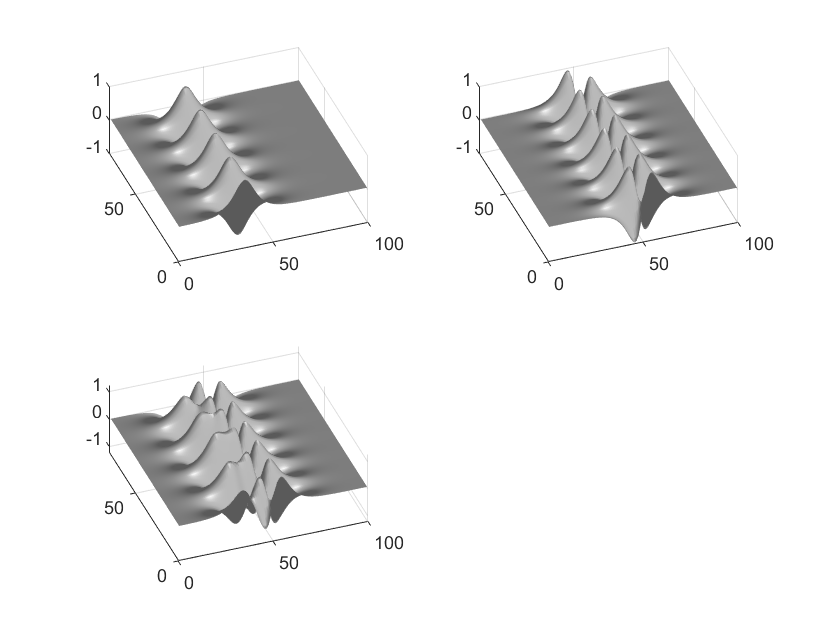

f1=sech(X+3).*(1*exp(i*2.3*T));
f2=(sech(X).*tanh(X)).*(2*exp(i*2.8*T));
f=f1+f2;
 
subplot(2,2,1), surfl(real(f1)), shading interp, colormap(gray), view(-20,60)
subplot(2,2,2), surfl(real(f2)), shading interp,colormap(gray), view(-20,60)
subplot(2,2,3), surfl(real(f)), shading interp,colormap(gray), view(-20,60) 

[u,s,v]=svd(f');
 
figure(2)
subplot(4,3,1), plot(diag(s)/sum(diag(s)),'ko','Linewidth',[2])
subplot(4,1,2), plot(t,v(:,1)/max(v(:,1)),t,v(:,2)/max(v(:,2)),'Linewidth',[2])

subplot(4,1,3), plot(x,u(:,1)/max(u(:,1)),'Linewidth',[2])

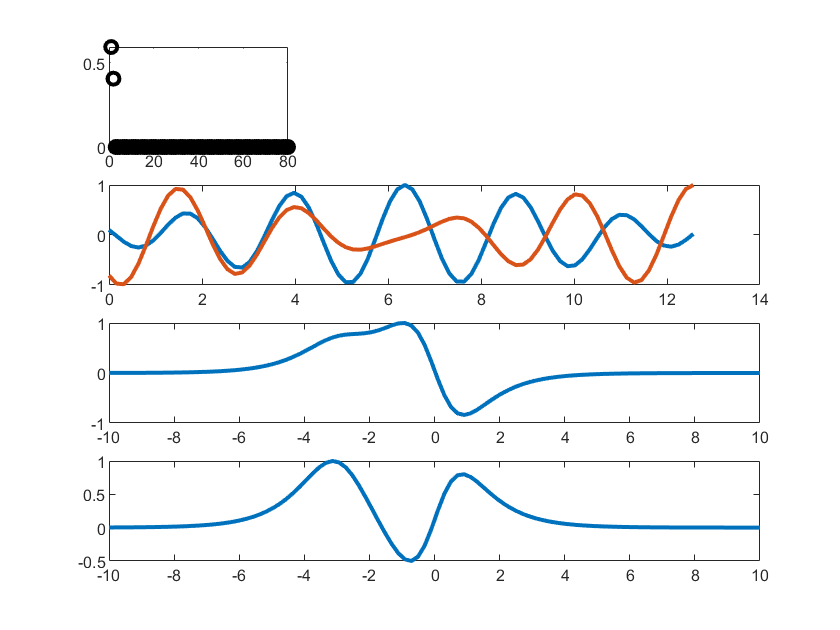

subplot(4,1,4), plot(x,u(:,2)/max(u(:,2)),'Linewidth',[2])

X = f.'; X1 = X(:,1:end-1); X2 = X(:,2:end);
r=2;

[U2,Sigma2,V2] = svd(X1,'econ'); U=U2(:,1:r); Sigma=Sigma2(1:r,1:r); V=V2(:,1:r);
Atilde = U'*X2*V/Sigma;    
[W,D] = eig(Atilde);    
Phi = X2*V/Sigma*W;
    
mu = diag(D);
omega = log(mu)/dt;

u0=f(1,:).';
y0 = Phi\u0;  % pseudo-inverse initial conditions
u_modes = zeros(r,length(t));
for iter = 1:length(t)
     u_modes(:,iter) =(y0.*exp(omega*t(iter)));
end
u_dmd = Phi*u_modes;

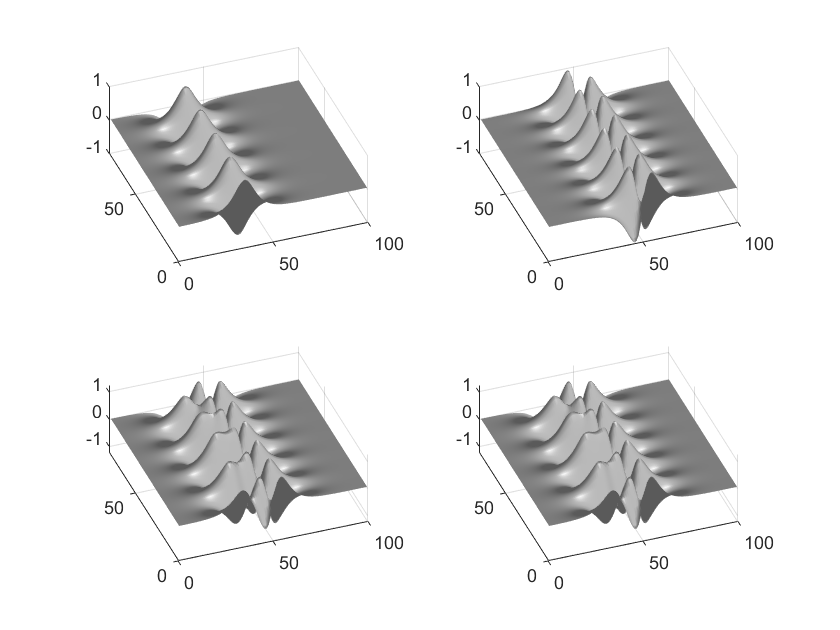

figure(1)
subplot(2,2,4)
surfl(real(u_dmd.')), shading interp,colormap(gray), view(-20,60)


figure(2), 
subplot(4,3,2), plot(diag(Sigma2)/sum(diag(Sigma2)),'ko','Linewidth',[2])
subplot(4,1,3), hold on, plot(x,-Phi(:,1)/max(Phi(:,1)),'Linewidth',[2])

subplot(4,1,4), hold on, plot(x,Phi(:,2)/max(Phi(:,2)),'Linewidth',[2])

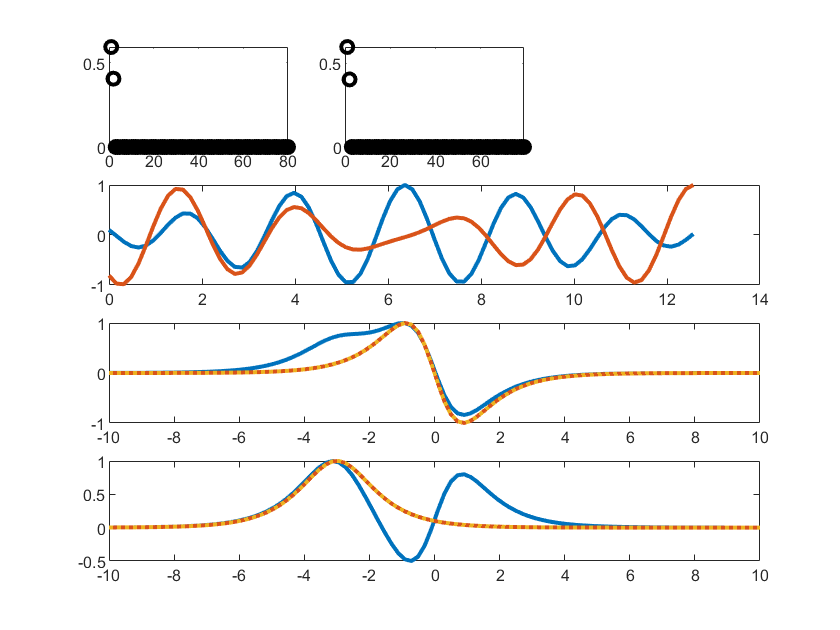


subplot(4,1,3), plot(x,-sech(x).*tanh(x)/max(sech(x).*tanh(x)),':','Linewidth',[2])
subplot(4,1,4), plot(x,sech(x+3)/max(sech(x+3)),':','Linewidth',[2])